% Assignment Code: Hybrid Traditional + AI Pipeline
close all; clear; clc;
% ---------------------------------------------------
% Section 1: Load Image and AI Network
% ---------------------------------------------------
% Load a sample image of a flower
% We will try to classify the isolated flower using AI
targetImage = imread('peppers.png'); % Using a common sample image
% Load a pre-trained SqueezeNet network for classification (a small, fast CNN)
disp('Loading pre-trained AI network (SqueezeNet)...');

Loading pre-trained AI network (SqueezeNet)...


net = squeezenet;
disp('Network loaded.');

Network loaded.


figure('Name', 'Hybrid Pipeline Images');
subplot(2, 2, 1); imshow(targetImage); title('Original Image');
% ---------------------------------------------------
% Section 2: Traditional Method (Color Segmentation using K-Means)
% Role: Isolate the main object of interest using a traditional algorithm.
% ---------------------------------------------------
disp('Applying traditional color segmentation (K-Means)...');

Applying traditional color segmentation (K-Means)...


% Reshape image for k-means clustering based on color
imgLab = rgb2lab(targetImage);
ab = imgLab(:,:,2:3);
ab = im2single(ab);
pixelLabels = imsegkmeans(ab, 2); % Cluster into 2 colors
% Create a mask to isolate the main object (assuming the object is Cluster 2)
mask = pixelLabels == 2;
% Apply the mask to the original image to get the isolated flower area
isolatedObject = targetImage;
isolatedObject(repmat(~mask, 1, 1, 3)) = 0; % Set background pixels to black
subplot(2, 2, 2); imshow(mask); title('Traditional Mask (K-Means)');
subplot(2, 2, 3); imshow(isolatedObject); title('Isolated Object (Input to AI)');
% ---------------------------------------------------
% Section 3: AI Method (Image Classification)
% Role: Use deep learning to classify the isolated object.
% ---------------------------------------------------
disp('Running AI classification on the isolated object...');

Running AI classification on the isolated object...


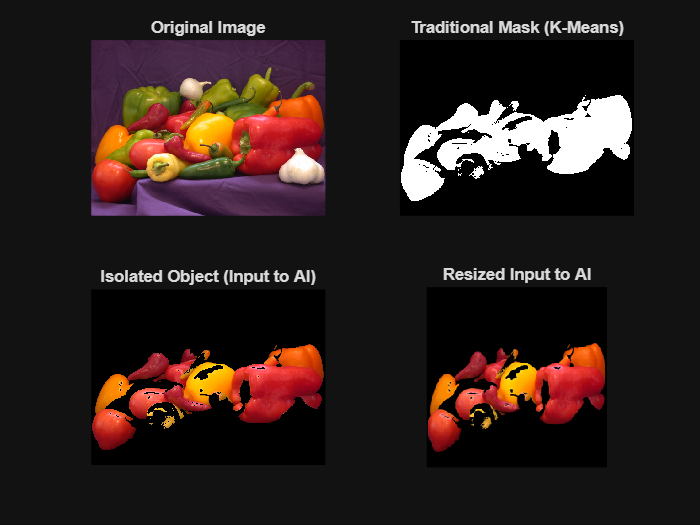

% The AI network requires a specific input size (SqueezeNet needs 227x227x3)
inputSize = net.Layers(1).InputSize;
resizedObject = imresize(isolatedObject, [inputSize(1) inputSize(2)]);
% Classify the image using the pre-trained network
[YPred, probs] = classify(net, resizedObject);
% ---------------------------------------------------
% Section 4: Results Analysis
% ---------------------------------------------------
subplot(2, 2, 4); imshow(resizedObject); title('Resized Input to AI');

fprintf('\n--- Hybrid Pipeline Results ---\n');


--- Hybrid Pipeline Results ---


fprintf('The AI model classified the isolated object as: **%s**\n', string(YPred));

The AI model classified the isolated object as: **sea slug**


fprintf('Confidence (Probability): %.2f%%\n', max(probs)*100);

Confidence (Probability): 32.84%


% The idea is that isolating the *object* first (traditional) helps the
% *classifier* (AI) focus purely on the target, improving accuracy
% compared to just feeding the original, complex background image into the AI.